# MATLAB, The MATrix LABoratory

## Prehľad prostredia / Environment overview

Ľavý panel (Left pane)

- Current folder

Stredný panel (Middle pane)

- Editor, Command window

Pravý panel (Right pane)

- Workspace

Horné menu (Top menu)

- Run

- Run section

- Apps

## **Stránka predmetu**

[https://sites.google.com/stuba.sk/vgg/dsozb/general-info](https://sites.google.com/stuba.sk/vgg/dsozb/general-info) 

## Základné príkazy

Úloha: Vytvorte si 2 premenné a inicializujte ich náhodným číslom. Vykonajte ich vynásobenie, ktorý výsledok ako jediný vypíšete na konzolu.

## Basic commands

Task: Create 2 variables and initialize them with random number. Multiply these 2 variables and print out the result (don't print out first 2 variables being added).

% Riesenie / Solution
var1 = rand();
var2 = rand();
res = foo*bar

res = 0.0327

## Maticové operácie

Úloha č.1: 

Vytvorte riadkový vektor *a* s hodnotami: 2; 3.5; 4.2; 5; -1.5

Vytvorte riadkový vektor *b* s hodnotami: -2; 3; -1.8; 1; 0.5

Vykonajte sčítanie dvoch vektorov po indexoch a vypíšte súčet čísel vo výslednom vektore.

Vykonajte vynásobenie týchto dvoch vektorov po indexoch a vypíšte štandardnú odchýlku výsledného vektora.

## Matrix operations

Task no.1: 

Create row vector a with following values: 2; 3.5; 4.2; 5; -1.5

Create row vector b with following values: -2; 3; -1.8; 1; 0.5

Add these two vectors by indices and print out the resulting vector.

Multiply these two vectors by indices and print out standard deviation of the resulting vector.

% Riesenie / Solution
a = [2 3.5 4.2 5 -1.5];
b = [-2 3 -1.8 1 0.5];
a+b

ans =          0    6.5000    2.4000    6.0000   -1.0000


res = a .* b;
std(res)

ans = 7.1925

Úloha č.2:

Vytvorte riadkový vektor *a* veľkosti 1x111 s hodnotami od 0 po 55 s krokom 0,5.

Vytvorte stĺpcový vektor *b* veľkosti 111x1 s hodnotami od 0 po 55 s krokom 0,5.

Vykonajte vynásobenie vektorov dvomi spôsobmi:

- a * b

- b * a

Porovnajte výsledok (je rovnaky?)

Task no.2:

Create row vector a with size 1x111 with values from 0 to 55 with step of 0.5

Create column vector b with size 1x111 with values from 0 to 55 with step of 0.5

Multiply these two vectors following ways:

- a * b

- b * a

Compare the results (are they equal ?):

% Riesenie / Solution
a = [0:.5:55];
b = a.';
a*b

ans = 1.1243e+05

b*a

ans = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0003    0.0005    0.0008    0.0010    0.0013    0.0015    0.0018    0.0020    0.0022    0.0025    0.0027    0.0030    0.0032    0.0035    0.0037    0.0040    0.0043    0.0045    0.0047    0.0050    0.0053    0.0055    0.0057    0.0060    0.0063    0.0065    0.0067    0.0070    0.0073    0.0075    0.0077    0.0080    0.0083    0.0085    0.0088    0.0090    0.0092    0.0095    0.0097    0.0100    0.0103    0.0105    0.0107    0.0110    0.0112    0.0115    0.0118  

**Odpoveď**: Výsledok a*b je skalár, výsledok b*a je matica, nie sú rovnaké.

Úloha č.3: (indexovanie)

Vytvorte si dve matice veľkosti 5x5 a inicializujte ich náhodnými číslami v intervale <0;5>

Vykonajte vynásobenie prvých troch stĺpcov prvej matice s 1,2,4 riadkom z druhej matice

Task no. 3:(indexing)

Crete two matrices of size 5x5 and initialize them with random values on interval <0;5>

Mulitply first 3 columns of first matrix with 1,2,4 row of the second matrix.

% Riesenie / Solution
matrix1 = rand(5,5) * 5;
matrix2 = rand(5,5) * 5;
matrix1(:,1:3) * matrix2([1:2,4],:)

ans =     2.5335   27.5347    4.4213   23.7788   27.2653
   18.0935   23.0734    3.0112   15.5884   24.8100
   10.3962   32.8402    6.8010   33.0819   35.4503
   17.9375   36.5683    7.2377   34.8950   40.1917
   10.9817   29.3939    5.9384   28.8783   31.8528


## **Grafy - vykresľovanie**

Úloha č.1:

Zobrazte základný sínusový signál na intervale <0;1> s krokom 0.01

Pomôcka: plot() 

Task no.1:

Display basic sine signal on interval <0;1> with step of 0.01

Hint: plot() 

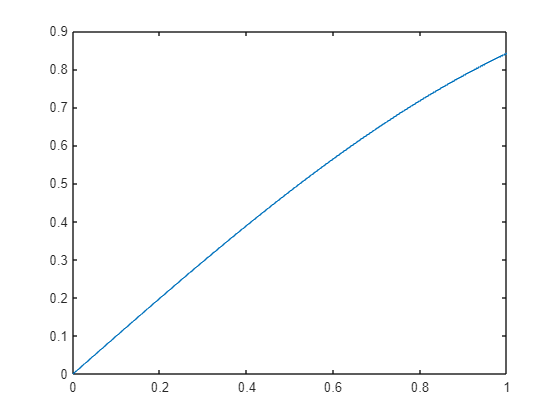

% Riesenie / Solution
x = [0:0.01:1];
y = sin(x);
plot(x, y)

Úloha č.2:

Pomenujte osi predošlej vizualizácie.

Task no.2:

Name axes of the chart created in previous step.

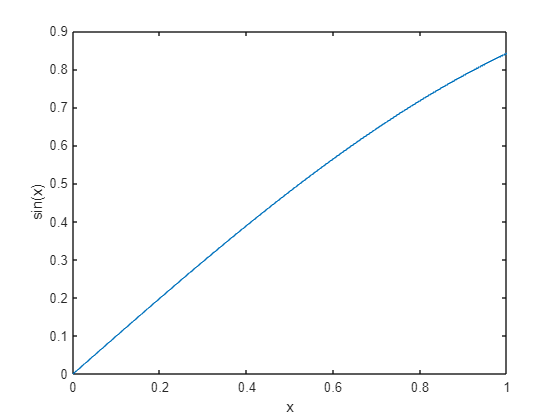

% Riesenie / Solution
xlabel('x')
ylabel('sin(x)')

Úloha č.3:

Vytvorte stĺpcový vektor s vypočítanými hodnotami funkcie sínus z predošlej úlohy a vynásobte ho tým istým, ale riadkovým vektorom (výsledok je matica)

Vizualizujte túto maticu funkciou: surf()

Task no.3:

Create column vector with values from sine fuction and multiply it by the transposed version of itself (result should be matrix).

Visualize this matrix with function: surf()

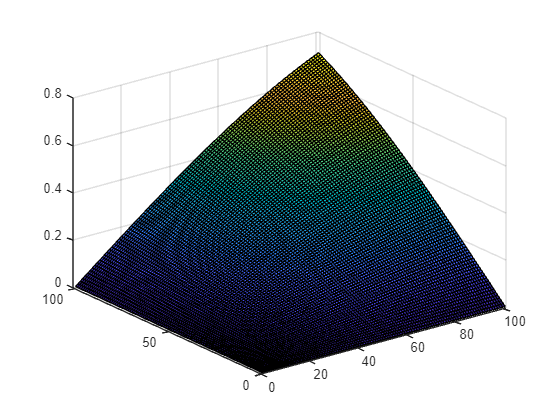

% Riesenie / Solution
foo = y.' * y;  % y je row vector, transponovaním dostaneme column ktorý ďalej násobíme 
surf(foo)